% Author: Edward L. Rivera Matlab Code 

% Description: The purpose of this script is to find/extract well/arm transition
% sequences of length n and evaluate statistical significance of occurence via Permutation testing 

# Load data 

load Cohort6-May-31-2023.mat % load data 

# Extract Test Session

test=data(75).WellTransitions{2}.currentWell % sample session

test =      1
     2
     3
     2
     1
     3
     2
     1
     3
     1


transitionseq = 131×3 table
        sequences        repeats    significance
    _________________    _______    ____________

    {[          1 2]}    {[18]}         NaN     
    {[          2 3]}    {[17]}         NaN     
    {[        1 2 3]}    {[17]}         NaN     
    {[          3 1]}    {[16]}         NaN     
    {[        2 3 1]}    {[15]}         NaN     
    {[        3 1 2]}    {[15]}         NaN     
    {[      1 2 3 1]}    {[15]}         NaN     
    {[      2 3 1 2]}    {[14]}         NaN     
    {[      3 1 2 3]}    {[14]}         NaN     
    {[    1 2 3 1 2]}    {[14]}         NaN     
    {[    2 3 1 2 3]}    {[13]}         NaN     
    {[    3 1 2 3 1]}    {[13]}         NaN     
    {[  1 2 3 1 2 3]}    {[13]}         NaN     
    {[  2 3 1 2 3 1]}    {[13]}         NaN     
    {[1 2 3 1 2 3 1]}    {[13]}         NaN     
    {[  3 1 2 3 1 2]}    {[12]}     

# Extract/find well transition sequences of length n and the associated frequency of occurence 


transitionseq=find_patterns(test); % use find_patterns.m function to extract repeating sequences of length >1
transitionseq=table(transitionseq(:,1),transitionseq(:,2),nan(height(transitionseq),1),'VariableNames',["sequences" "repeats" "significance"]); % create table 
transitionseq=sortrows(transitionseq,"repeats","descend"); % sort sequences by the number of repeats 

soi=[]; % vector containing the indexes of sequences of a particular length e.g., all sequences of length 3
for i=1:height(transitionseq) % iterate across the sequences
    if length(transitionseq.sequences{i})==3 % This number can be modfied to extract sequences of given length e.g., 4,5 etc 
        soi(end+1)=i; % extract index of target sequence 
    end
    
end

transitionseq=transitionseq(soi,:); % show only sequences of length 3

# Permutation Test

Analyzing Sequence Number:1


1


Analyzing Sequence Number:2


1


Analyzing Sequence Number:3


1


Analyzing Sequence Number:4


0


Analyzing Sequence Number:5


0


Analyzing Sequence Number:6


0


Analyzing Sequence Number:7


0


Analyzing Sequence Number:8


0


transitionseq = 8×3 table
    sequences    repeats    significance
    _________    _______    ____________

    {[1 2 3]}    {[17]}          1      
    {[2 3 1]}    {[15]}          1      
    {[3 1 2]}    {[15]}          1      
    {[3 2 1]}    {[ 4]}          0      
    {[2 1 3]}    {[ 3]}          0      
    {[1 3 2]}    {[ 2]}          0      
    {[2 1 2]}    {[ 2]}          0      
    {[2 3 2]}    {[ 2]}          0      


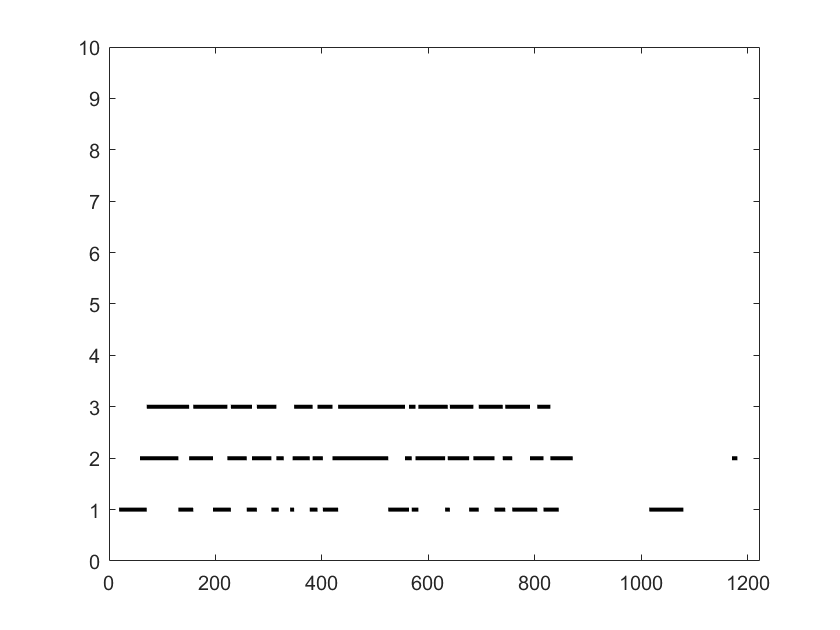


for seq=1:height(transitionseq) % iterate across sequences 
    disp(strcat('Analyzing Sequence Number:',string(seq))); % display status 
    nulldist=[]; % vector containing the number of repeats 
    maxiterations=5000; % maximum number of iterations 
    
    for iteration=1:maxiterations % perform each iteration for generating the null distribution 
        permutedtransitions=test(randperm(length(test))); % randomly permute well transition sequence 
        sequencerepeats=find_patterns(permutedtransitions); % use find_patterns.m function to extract all sequences
        sequencerepeats=table(sequencerepeats(:,1),sequencerepeats(:,2),'VariableNames',["sequences" "repeats"]); % create table 
        
        for permutedsequence=1:height(sequencerepeats) % iterate across sequences 
            if isequal(transitionseq.sequences(seq),sequencerepeats.sequences(permutedsequence)) % find common sequence between ral data and random agent 
                nulldist(end+1)=sequencerepeats.repeats{permutedsequence}; % extract number of repeats for that given sequence 
                
            end
        end

        
    end
    
    pvalue=length(find(nulldist>transitionseq.repeats{seq}))/length(nulldist); % Permutation test 
    
    
    if pvalue<0.05
        transitionseq.significance(seq)=1; % 1 if significant
        disp(string(1));
    else
        transitionseq.significance(seq)=0; % 0 otherwise 
        disp(string(0));
        
    end
    
end